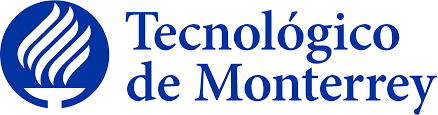

### Fundamentación de robótica (TE3001B)

## Examen Final 6 (Torque y fuerzas) Parte 2

### Pamela Hernández Montero A0173636

**Objetivo**

Obtener el modelo del torque de cada articulación, la matriz de inercia, el modelo de las fuerzas centripetas y de Coriolis y el modelo del par gravitacional para cada una de las siguientes configuraciones para un robot de 2GDL.

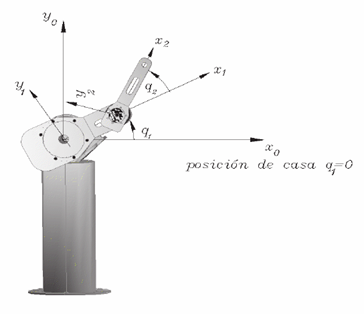

**Introducción:**

La cinemática de un robot se refiere a la descripción geométrica del movimiento y no en las causas físicas que lo generan; permite determinar la posición y orientación del extremo del robot en función de las posiciones de sus articulaciones.

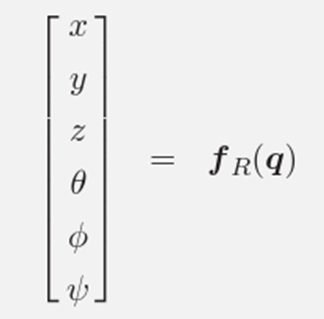

Por otro lado la cinemática diferencial relaciona las velocidades de las articulaciones y las velocidades resultantes del extremo del robot. La cinemática diferencial directa es la derivada con respecto al tiempo de la cinemática directa.

%Limpieza de pantalla
clear all
close all
clc

Se definen variables simbólicas para representar el ángulo de la articulación, su velocidad y aceleración, así como parámetros físicos como la masa, los momentos de inercia y la geometría del eslabón. Se configura el robot como una junta rotacional y se calcula el número de grados de libertad del sistema. 

%Declaración de variables simbólicas
syms th1(t) th2(t) t  %Angulo de la articulación
syms th1p(t) th2p(t)  %Velocidad de la articulación
syms th1pp(t) th2pp(t) %Aceleración de la articulación
syms m1  Ixx1 Iyy1 Izz1 m2 Ixx2 Iyy2 Izz2 %Masa y matrices de Inercia
syms l1 lc1 l2 lc2  %l=longitud del eslabon y lc=distancia al centro de masa del eslabón
syms pi g a cero

%Creamos el vector de coordenadas articulares
Q= [th1, th2];
%Creamos el vector de velocidades articulares(1GDL)
Qp= [th1p; th2p];
%Creamos el vector de aceleraciones articulares(1GDL)
Qpp= [th1pp; th2pp]; %se utiliza este formato para simplificar la impresion de resultados

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

Se describe la construcción de la matriz homogénea para cada articulación.

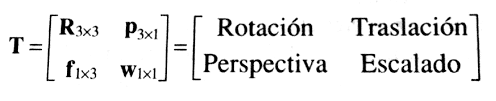

% Definición de la posición de las articulaciones
P(:,:,1) = [l1*cos(th1); 
            l1*sin(th1); 0]; % Posición de la junta 1 respecto al origen
P(:,:,2) = [l2*cos(th2);
            l2*sin(th2);0]; % Posición de la junta 2 respecto a la junta 1
% Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1) = [cos(th1) -sin(th1) 0;
            sin(th1) cos(th1)  0;
            0          0     1];
%Matriz de rotación de la articulación 2 respecto a 1
R(:,:,2) = [cos(th2) -sin(th2) 0;
            sin(th2)  cos(th2) 0;
            0        0       1];
% Creamos un vector de ceros
Vector_zeros = zeros(1, 3);

Se establece las bases para representar la transformación y características espaciales del robot.

% Inicializamos las matrices de transformación homogéneas locales
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_zeros 1]);

% Inicializamos las matrices de transformación homogénea global
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_zeros 1]);

Calcular las matrices de transformación tanto locales como globales para cada articulación.

% Inicializamos los vectores de posición y rotacion
PO(:,:,GDL) = P(:,:,GDL);
RO(:,:,GDL) = R(:,:,GDL);
for i = 1:GDL
    i_str = num2str(i);
    % Locales 
    disp(strcat("Matriz de transformación local A", i_str));
    A(:,:,i) = simplify([R(:,:,i) P(:,:,i); Vector_zeros 1]);
    pretty(A(:,:,i));
    % Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i);
    end
    disp(strcat("Matriz de transformación global T", i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));
    % Obtenemos la matriz de rotación "RO" y el vector de translación PO de
    % la matriz de transformación homogénea global T(:,:,GDL)
    RO(:,:,i) = T(1:3, 1:3, i);
    PO(:,:,i) = T(1:3, 4, i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i))
end

Matriz de transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Matriz de transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de transformación global T2


/ #2, -#1, 0, l1 cos(th1(t)) + l2 #2 \
|                                    |
| #1,  #2, 0, l1 sin(th1(t)) + l2 #1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




/ cos(th1(t) + th2(t)), -sin(th1(t) + th2(t)), 0 \
|                                                |
| sin(th1(t) + th2(t)),  cos(th1(t) + th2(t)), 0 |
|                                                |
\           0,                    0,           1 /



/ l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                          |
| l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                          |
\                     0                    /



El Jacobiano es una matriz que relaciona las velocidades de las articulaciones del robot con las velocidades del extremo del robot en el espacio de trabajo. Se ocupa para analizar la cinemática del robot y entender cómo los **cambios en las velocidades** de las articulaciones afectan el **movimiento del extremo** del robot.

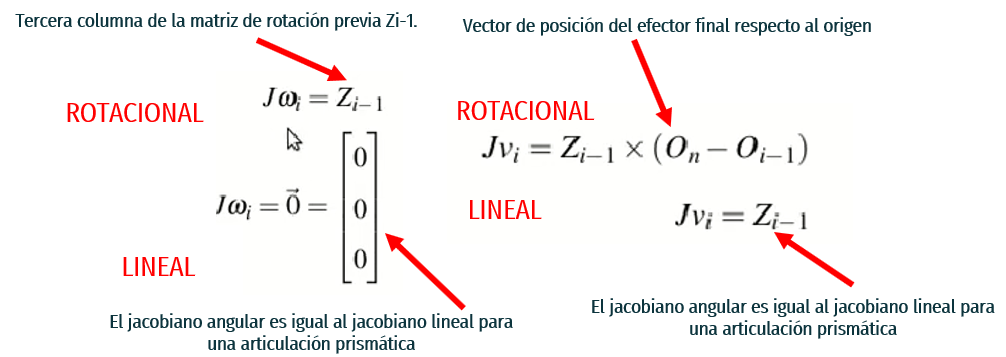

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
        %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    
Jv_a = simplify(Jv_a);
Jw_a = simplify(Jw_a);
disp("Jacobiano lineal obtenido de forma analítica"); pretty(Jv_a);

Jacobiano lineal obtenido de forma analítica
/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)), -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)),   l2 cos(th1(t) + th2(t)) |
|                                                                      |
\                      0,                                 0            /



disp("Jacobiano angular obtenido de forma analítica");pretty(Jw_a);

Jacobiano angular obtenido de forma analítica
/ 0, 0 \
|      |
| 0, 0 |
|      |
\ 1, 1 /



%Matriz de Jacobiano Completa
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
disp('Matriz de Jacobiano');pretty(Jacobiano);

Matriz de Jacobiano
/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)), -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)),   l2 cos(th1(t) + th2(t)) |
|                                                                      |
|                      0,                                 0            |
|                                                                      |
|                      0,                                 0            |
|                                                                      |
|                      0,                                 0            |
|                                                                      |
\                      1,                                 1            /



Con el Jacobiano obtenemos vectores de velocidades lineales y angulares que describen cómo cambian las posiciones y orientaciones del extremo del robot en respuesta a las velocidades de las articulaciones. 

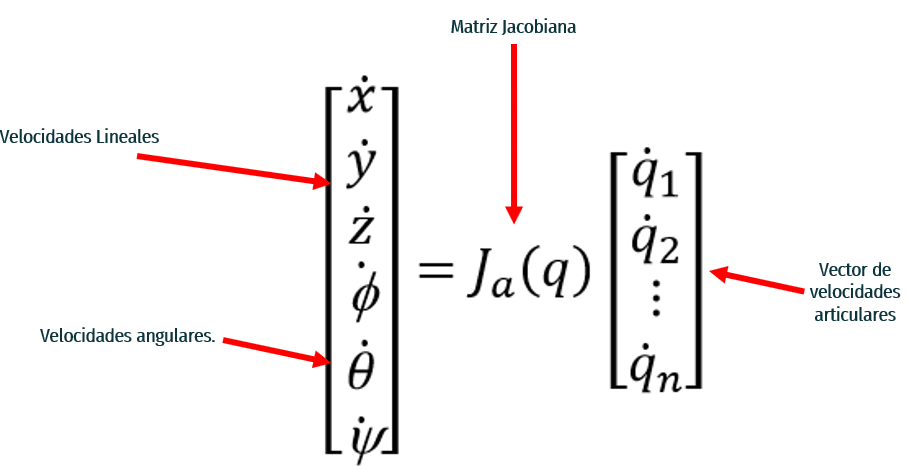

V =  simplify(Jv_a*Qp);
disp("Velocidad lineal obtenida mediante el Jacobiano lineal"); pretty(V);

Velocidad lineal obtenida mediante el Jacobiano lineal
/ - th1p(t) (l1 sin(th1(t)) + l2 #1) - l2 #1 th2p(t) \
|                                                    |
|  th1p(t) (l1 cos(th1(t)) + l2 #2) + l2 #2 th2p(t)  |
|                                                    |
\                          0                         /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




W = simplify(Jw_a*Qp);
disp("Velocidad angular mediante el Jacobiano angular"); pretty(W);

Velocidad angular mediante el Jacobiano angular
/         0         \
|                   |
|         0         |
|                   |
\ th1p(t) + th2p(t) /



A continuación se calcula la energía cinética de un eslabón del robot y obtiene los vectores de velocidades lineales y angulares asociados. Primero, se define la posición del **centro de masa** del eslabón respecto al origen y se crean **matrices de inercia** para el eslabón utilizando sus momentos principales. Luego, se extraen las **velocidades lineales y angulares **del robot en cada eje del espacio. Posteriormente, se calculan las velocidades para cada eslabón del robot utilizando el Jacobiano lineal y angular obtenido de forma analítica previamente. Esto se logra calculando las derivadas de las posiciones del extremo del robot respecto a las velocidades de las articulaciones. Finalmente, se obtienen los vectores de velocidades lineales y angulares asociados al eslabón del robot,

%Energía Cinética

%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
P01=subs(P(:,:,1)/2, l1, lc1);
P12=subs(P(:,:,2)/2, l2, lc2);

%Creamos matrices de inercia para cada eslabón
I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];
I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 

%Eslabón 1

%Calculamos el jacobiano lineal de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
if RP(k)==0 
   %Para las juntas de revolución
    try
        Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
        Jw_a1(:,k)= RO(:,3,k-1);
    catch
        Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
        Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
     end
 else
         %Para las juntas prismáticas
    try
        Jv_a1(:,k)= RO(:,3,k-1);
    catch
        Jv_a1(:,k)=[0,0,1];
    end
        Jw_a1(:,k)=[0,0,0];
 end
end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);

%Matriz de Jacobiano Completa
Jac1= [Jv_a1;
        Jw_a1];
Jacobiano1= simplify(Jac1);

%Obtenemos vectores de Velocidades Lineales y Angulares
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');pretty(V1);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1
/ -l1 sin(th1(t)) th1p(t) \
|                         |
|  l1 cos(th1(t)) th1p(t) |
|                         |
\            0            /



W1=simplify (Jw_a1*Qp(1));
disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1'); pretty(W1);

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1
/    0    \
|         |
|    0    |
|         |
\ th1p(t) /



Energia cinetica = Energia cinetica traslacional + Energia cinetica rotacional

La energía cinética describe la capacidad de un objeto en movimiento para realizar trabajo y causar cambios en su entorno durante una interacción.

%Calculamos la energía cinética para cada uno de los eslabones

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
K1= simplify (K1);
disp('Energía Cinética en el Eslabón 1');pretty (K1);

Energía Cinética en el Eslabón 1
              2            2     ______           __          2             2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 |lc1|  + 2 lc1 |l1| ) (2 l1 + lc1)
--------------- + -------------------------------------------------------------------------
       2                                           8 l1 lc1



%Eslabón 2
V2_Total= V+cross(W,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W)'*(I2*W);
K2= simplify (K2);
disp('Energía Cinética en el Eslabón 2');pretty (K2);

Energía Cinética en el Eslabón 2
                                                                                       /                                                                  ______  ___    \                                                                                                                          /                                                                  ______  ___    \
__ /                                                              lc2 sin(th2(t)) #1 \ | _______          __       ______  __    _______         __   sin(th2(t)) lc2 #2 |                                   __ /                                                              lc2 cos(th2(t)) #1 \ | _______          __       ______  __    _______         __   cos(th2(t)) lc2 #2 |
m2 | th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + ------------------ | | th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + ------------------ |           / _______   _______ \   m2 | th1p(

K_Total= simplify (K1+K2);
%pretty (K_Total);

Energia potencial gravitatoria

Se define como la energía que un objeto posee debido a su altura en relación con una referencia definida en el campo gravitatorio. 

%Calculamos la energía potencial para cada uno de los eslabones

%Obtenemos las alturas respecto a la gravedad
h1= P01(2); %Tomo la altura paralela al eje y
h2= P12(2); %Tomo la altura paralela al eje y

U1=m1*g*h1;
U2=m2*g*h2;

%Calculamos la energía potencial total
U_Total= U1 + U2;

El uso del Lagrangiano ofrece una manera elegante y eficiente de describir su dinámica y comportamiento. En mecánica clásica, el Lagrangiano, denotado típicamente como *L*, es una función que depende de las coordenadas generalizadas del sistema, así como de sus velocidades y posiblemente del tiempo. Matemáticamente, se define como la **diferencia entre la energía cinética *****T***** y la energía potencial *****V*** del sistema:

*L*=*T*−*V*

%Obtenemos el Lagrangiano
Lagrangiano= simplify (K_Total-U_Total);
pretty (Lagrangiano);

                                                                                                 /                                                                  ______  ___    \                                                                                                                          /                                                                  ______  ___    \
          __ /                                                              lc2 sin(th2(t)) #1 \ | _______          __       ______  __    _______         __   sin(th2(t)) lc2 #2 |                                   __ /                                                              lc2 cos(th2(t)) #1 \ | _______          __       ______  __    _______         __   cos(th2(t)) lc2 #2 |
          m2 | th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + ------------------ | | th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + ------------------ |           / _______   _______ \   m2 | th1p(t) 

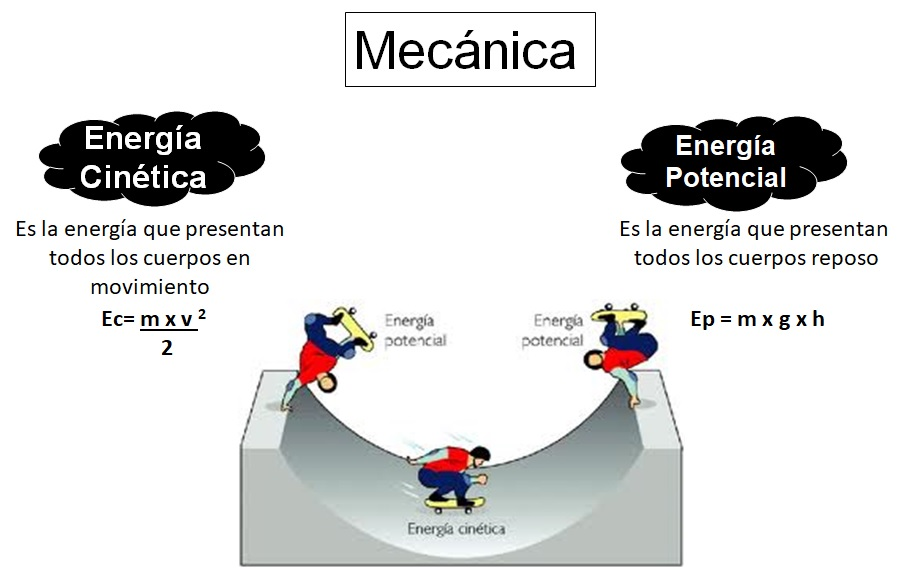

Estas energias son fundamentales para diseñar robots seguros, eficientes y capaces de realizar tareas de manera autónoma y precisa. La **energía cinética **permite evaluar la **velocidad** y el** movimiento** del robot, lo que es crucial para prevenir colisiones y garantizar un movimiento suave y controlado. Por otro lado, la **energía potencial** proporciona información sobre la **estabilidad** y el** equilibrio **del robot, lo que es esencial para evitar caídas y asegurar una operación segura en diversas condiciones.

%Modelo de Energía
H= simplify (K_Total+U_Total);
pretty (H)

                                                                                                 /                                                                  ______  ___    \                                                                                                                          /                                                                  ______  ___    \
          __ /                                                              lc2 sin(th2(t)) #1 \ | _______          __       ______  __    _______         __   sin(th2(t)) lc2 #2 |                                   __ /                                                              lc2 cos(th2(t)) #1 \ | _______          __       ______  __    _______         __   cos(th2(t)) lc2 #2 |
          m2 | th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + ------------------ | | th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + ------------------ |           / _______   _______ \   m2 | th1p(t) 

En sistemas con movimientos rotacionales, el torque puede considerarse como una fuerza generalizada y ser incluido en las ecuaciones de Euler-Lagrange, lo que permite que el Lagrangiano describa el movimiento del sistema teniendo en cuenta los efectos del torque.

%Lagrangiano derivado con respecto a la primera coordenada generalizada de velocidad

%Definimos un vector columna de derivadas con respecto al tiempo
%En este vector agrego las velocidades y aceleraciones
%Derivadas respecto al tiempo
Qd=[th1p(t); th2p(t); th1pp(t); th2pp(t)];

%Obtenemos las derivadas de la velocidad en la primera coordenada generalizada
dQ1=[diff(diff(Lagrangiano,th1p), th1),diff(diff(Lagrangiano,th1p), th2),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
 diff(diff(Lagrangiano,th1p), th1p),diff(diff(Lagrangiano,th1p), th2p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones

%Definimos el torque 1
t1= dQ1*Qd- diff(Lagrangiano, th1);

%Obtenemos las de derivadas de la velocidad en la segunda coordenada generalizada

dQ2=[diff(diff(Lagrangiano,th2p), th1),diff(diff(Lagrangiano,th2p), th2),... %Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 posiciones articulaciones
 diff(diff(Lagrangiano,th2p), th1p),diff(diff(Lagrangiano,th2p), th2p)];%Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 velocidades articulaciones

%Definimos el torque 2
t2= dQ2*Qd- diff(Lagrangiano, th2);


%Generación del Modelo Dinámico en forma matricial

%Matriz de Inercia
%Extraemos coeficientes de aceleraciones
M=[diff(t1, th1pp), diff(t1, th2pp);...
diff(t2, th1pp), diff(t2, th2pp)];
rank (M);
M=M(t);
disp('Matriz de inercia ='); pretty(M)

Matriz de inercia =
/                                                                                                    __                                __                          __                                                                    \
|        __         __         Izz1 |th1p(t)|        Izz1 #2        Izz1 |th1p(t)| #2   |th1p(t)| #3 m1 #1 (2 l1 + lc1)   |th1p(t)| #3 m1 #1 #2 (2 l1 + lc1)    #3 m1 #1 #2 (2 l1 + lc1)                                                 |
| Izz2 + m2 #8 #7 + m2 #6 #9 + -------------- + ----------------- - ----------------- + ------------------------------- - ---------------------------------- + -------------------------,                       #5                       |
|                                 sqrt(#4)        _______                    3/2               4 l1 lc1 sqrt(#4)                                3/2                      _______                                                         |
|                                       

- Las fuerzas centrípetas surgen cuando el robot se mueve en una **trayectoria curva**, manteniéndolo en esa trayectoria.

- Las fuerzas de Coriolis son fuerzas ficticias que aparecen debido a la** rotación del sistema de referencia** o a la propia aceleración angular del robot.

%Fuerzas Centrípetas y de Coriolis

%Definimos Mp
M11=[diff(M(1,1),th1), diff(M(1,1),th2)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 
M12=[diff(M(1,2),th1), diff(M(1,2),th2)]*Qp;

M21=[diff(M(2,1),th1), diff(M(2,1),th2)]*Qp;
M22=[diff(M(2,2),th1), diff(M(2,2),th2)]*Qp;

Mp=[M11, M12;...
M21, M22;];

%Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp;

%Definimos dk

dk=[diff(k, th1); diff(k, th2)];

%Fuerzas centrípetas y de Coriolis
C= Mp*Qp-dk

El "par" (o torque) es una medida de la tendencia de una fuerza a hacer **girar un objeto alrededor de un eje**, mientras que el "torque gravitacional" es el par producido por la **influencia de la gravedad **en un objeto sujeto a un campo gravitacional.

%Par Gravitacional se sustituyen las velocidades y aceleraciones por 0
r=cero;
a1=subs(t1, th1p, r);
a2=subs(a1, th2p, r);
a3=subs(a2, th1pp, r);
a4=subs(a3, th2pp, r);

%Torque gravitacional en el motor 1
G1=a4;

b1=subs(t2, th1p, r);
b2=subs(b1, th2p, r);
b3=subs(b2, th1pp, r);
b4=subs(b3, th2pp,r);

%Torque gravitacional en el motor 2
G2=b4;

% Vector de par gravitacional
G=[G1;G2]